# **Optimising the classification of feature-selective attention and visual perception in frequency-tagged electroencephalography data**

**Created by Angela I. Renton. Email: angie.renton23@gmail.com**

## Background

This script was written to apply a number of machine learning approaches to classify where feature-selective attention is allocated in real-time. This live script both trains and tests on concurrent presentation data, and allows you to select the participant, sliding window size, and combination of frequencies you would like to train on. 

The data analysed in this script was collected while participants performed a dot motion discrimination task on a set of flickering dots. We recorded continuous EEG data while participants performed this task (see **a **in figure below). Each 7 s trial consisted of a 2 s cue indication which colour participants should focus on, followed by a 15 s period which contained 5 coherent motion epochs (see **b **in figure below). Dots were presented either concurrently, such that black and white dots, flickering at 6 & 7.5 Hz (colour and frequency were counterbalanced) occurred concurrently, but participants responded only to motion in dots of one colour, or individually, such that only dots of one colour flickering at one frequency were presented at once (see **c **in figure below). See the associated Data Descriptor for a detailed account of the methods used to collect the data analysed here (link to come). 

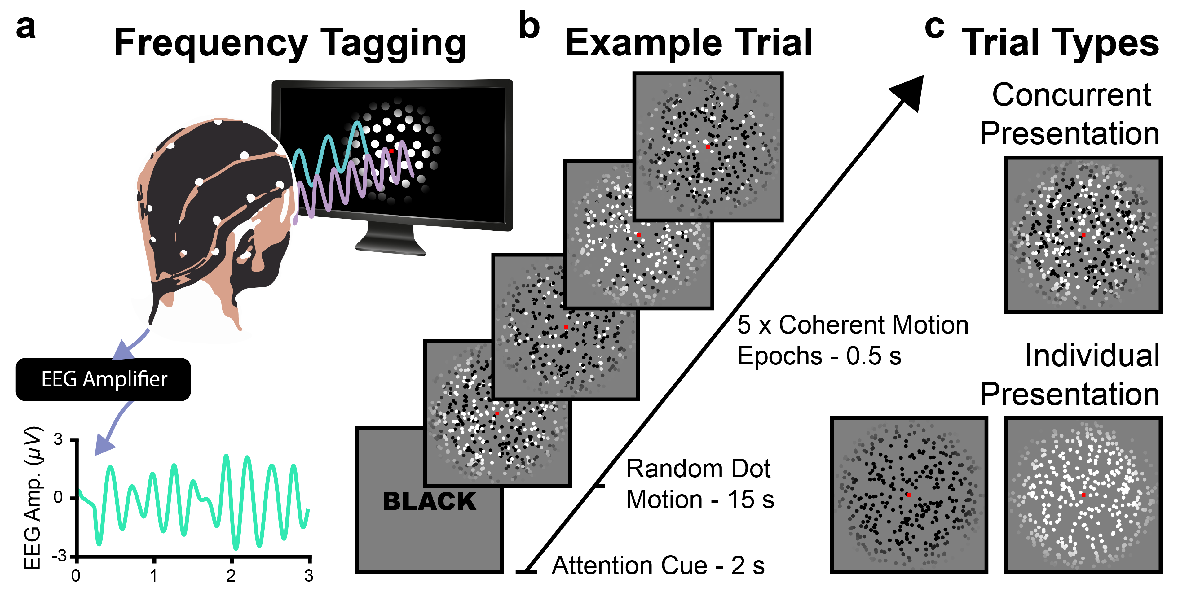

This script applies a processing pipeline, subjecting the data to a number of different analysis approaches and machine learning techniques in order to accurately classifiy the target of attention using single trial, frequency-tagged EEG data. The pipeline is as follows:

- (a) We extract epochs of sliding window data from each trial using a 0.25 s interval, and sliding window sizes ranging from 0.25 s to 4.00 s. 

- (b) We apply fast-fourier transforms (FFT's) to th epochs of data, extracting the amplitude at relevant frequencies. The epochs of data are all zero padded to 4.00 s to achieve equal spectral resolution across window sizes. 

- (c) We apply cannonical correlation analysis to the raw, sliding window data (without any frequency transforms)

- (d) We use z-scoring as well as a number of different machine learning techniques to classify the attended frequency using the FFT data. 

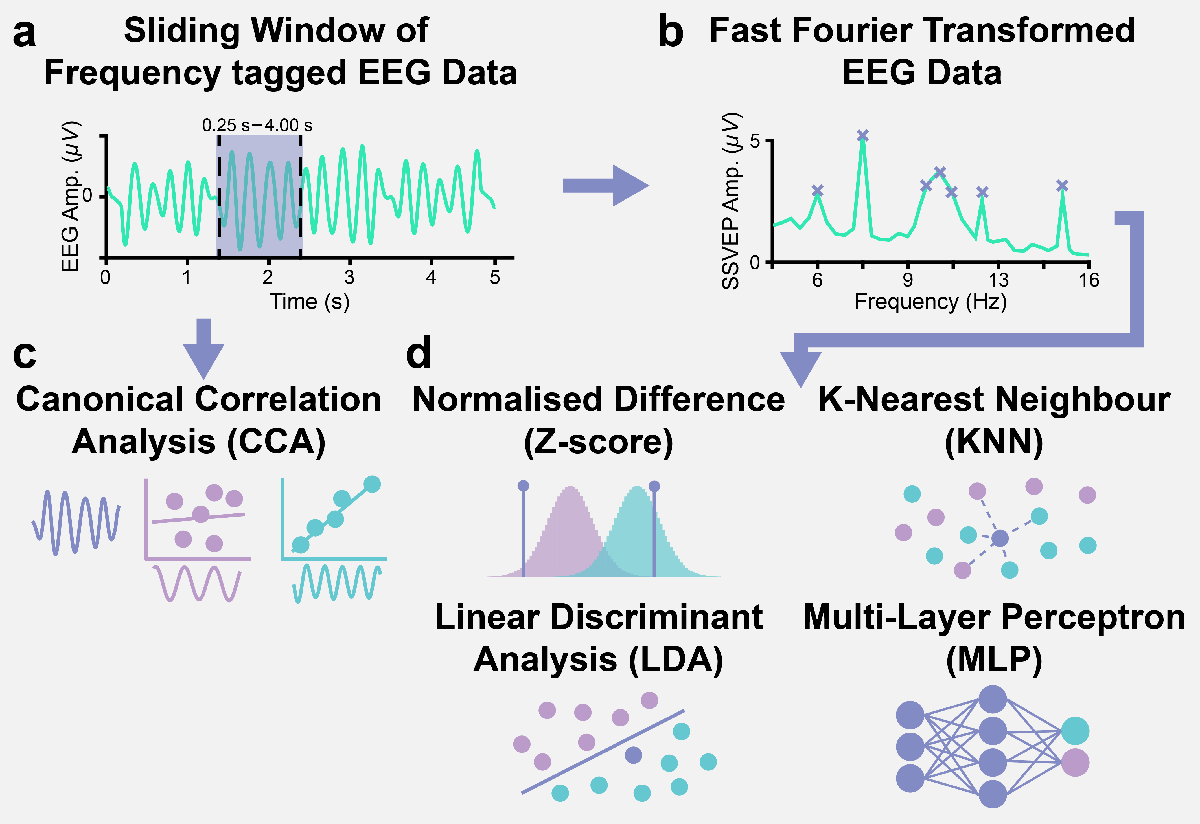

## Dependencies 

fieldtrip toolbox: [http://www.fieldtriptoolbox.org/](http://www.fieldtriptoolbox.org/)

*The data is stored in the BIDS format, and loaded in using fieldtrip. If you would prefer not to download fieldtrip, simply change the data directory to "sourcedata" (within the data folder), and use the origional matlab files containing the EEG data. *

## **Getting Set Up**

### **Housecleaning**

We'll clean up matlab before running anything, and add the "functions" directory, which contains some helpful scripts. 

clear
clc
close all
cd 'R:\FTATTNCLAS-Q1355\RTAttnselectMethods\RTAttnSelectMethods_SOLC\AnalysisScripts_FINAL'
addpath('functions/');

### Select settings for this run

This setting contols which participant (1 - 30) training and testing are run on.

*Note that two subjects were excluded (7 & 19) due to techincal difficulties with the recording session, so subject 7 in this drop down menu actually corresponds to subject 8 in the data. *

SUB = 1

SUB = 1

Set sliding window size

chunkSizeIterator = 5

chunkSizeIterator = 5

Set Frequencies to use

% HzState = {'Basic' 'Harmonic' 'Alpha' 'AlphaPlusHarmonic'}

%  Hz = [6 7.5 12 15];

HZSTATE = 1

HZSTATE = 1

### More general settings

ATTNSTATE =1

ATTNSTATE = 1

str.SNRState = {'amp' 'SNR'};
str.HzState = {'Basic' 'Harmonic' 'Alpha' 'AlphaPlusHarmonic'};

options.collate=0;
setupSettingsBIDS


### Get EEG data and metadata

Here we extract the trials of EEG data, using the BIDS formatted EEG files:

processing channel { 'Iz' 'Oz' 'POz' 'O1' 'O2' 'TRIG' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 2 seconds


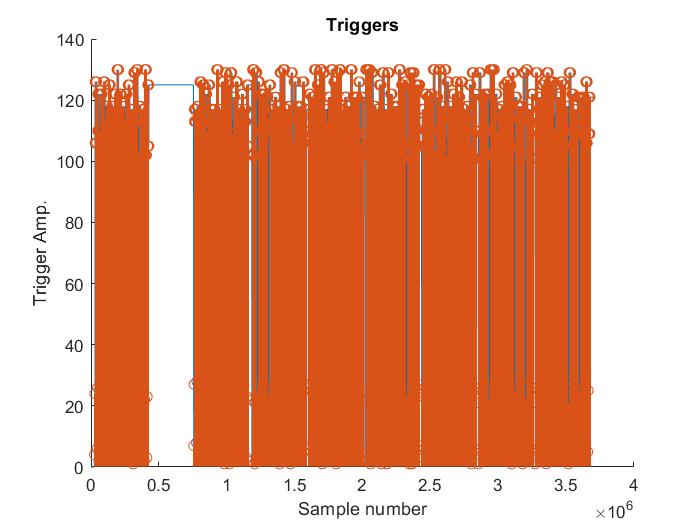

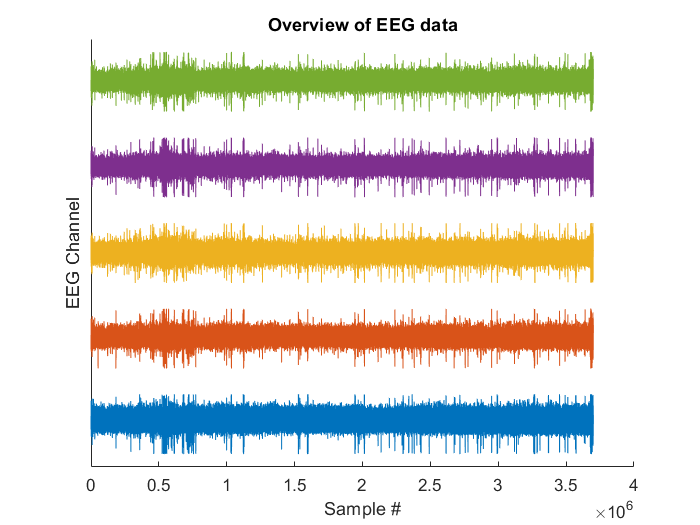

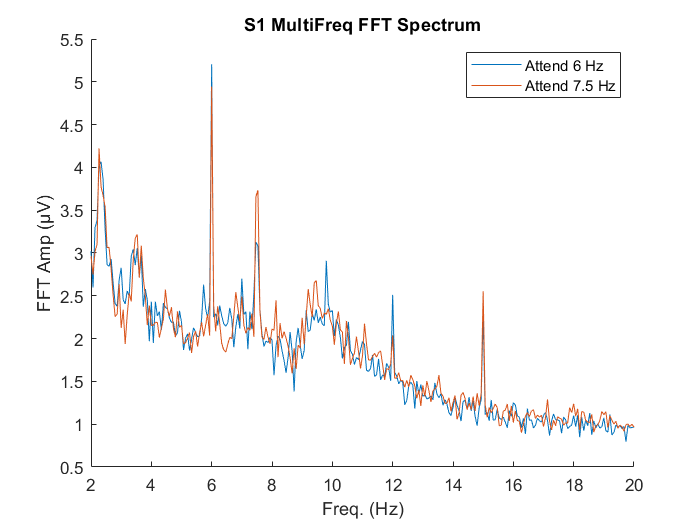

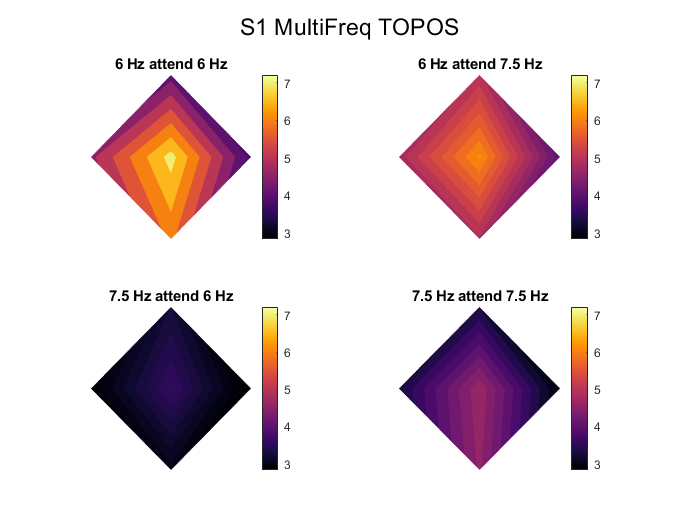

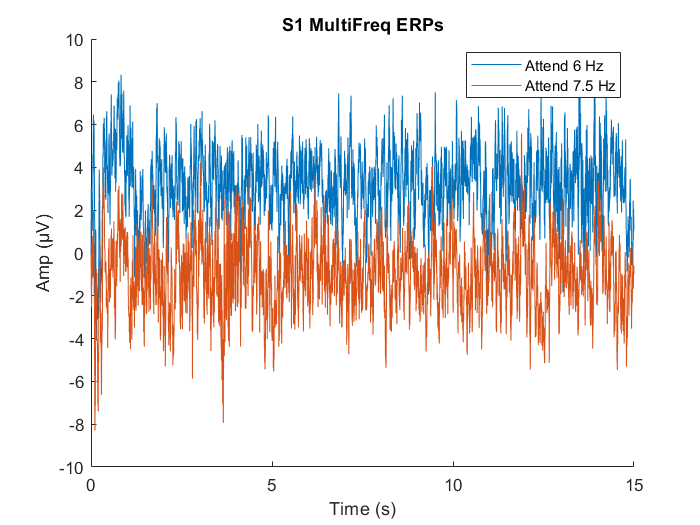

getEEGBIDS

### Generate CCA Templates

The canonical correlation analysis relies on matching data to a number of templates of idealised SSVEPs for attending to different frequencies. Here, we generate those templates by calculating ERPs of the SSVEPs, and generating sinusoids which match the phase of the SSVEPs. The process of calculating phase for each frequency and harmonic is as follows:

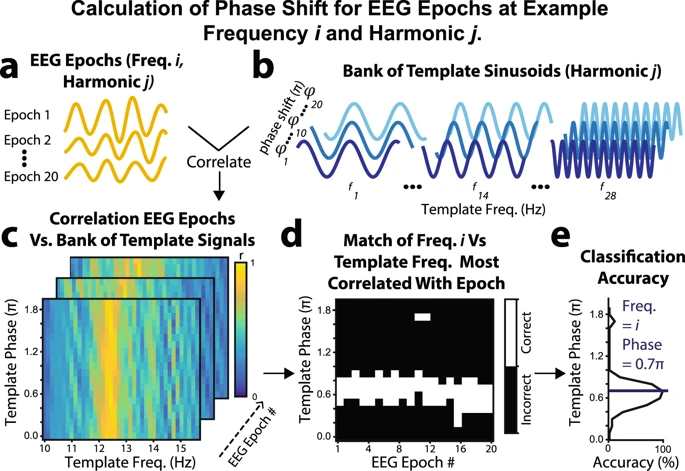

 For a full description of this method, see: 

Renton, A.I., Mattingley, J.B. & Painter, D.R. Optimising non-invasive brain-computer interface systems for free communication between naïve human participants. *Sci Rep* **9, **18705 (2019). [https://doi.org/10.1038/s41598-019-55166-y](https://doi.org/10.1038/s41598-019-55166-y)

generateCCATemplates

### Setup sliding window settings

Set up some variables that represent how the data is split up for this sliding window size

chunksize = samples.chunksizes(chunkSizeIterator); % Choose chunksize

samplepoints =  chunksize  : samples.slidingwindow : samples.trial; % The points we would hypothetically be calculating this at in realtime
n.chunks = length(samplepoints);

% Display current sliding window size
disp(['Epoch Length: ' num2str(time.chunksizes(chunkSizeIterator)) ' s, ' num2str(n.chunks) ' chunks'])

Epoch Length: 2 s, 53 chunks


### Sliding window data extraction

We don't want to save the data separately for every data size, so we extract this separately for every chunk length. We extract the various chunks of the size we're working on at the moment and allocate data and labels for this chunksize

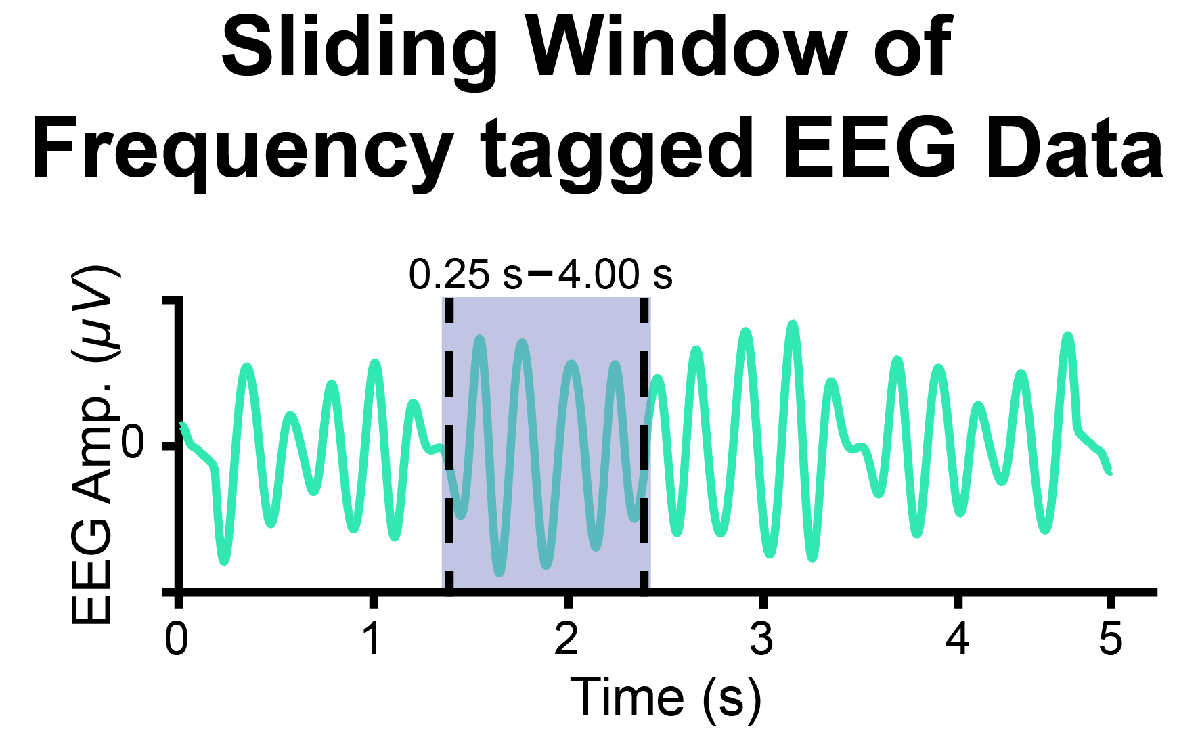

DATA = NaN(chunksize, n.channels, n.chunks * n.trials);
LABELS = NaN( n.chunks * n.trials,4);

counter = 0;
for TRIAL = 1:n.trials
    for CHUNK = 1:n.chunks
        counter = counter + 1;
        start = samplepoints(CHUNK)-chunksize +1;
        stop = samplepoints(CHUNK);
        
        DATA(:,:,counter) = TRIAL_EEG(start:stop, :, TRIAL); % Each chunk will be used for training.
        
        LABELS(counter,1) = LABELS_EEG(TRIAL);
        LABELS(counter,2) = TRIAL;
        LABELS(counter,3) = CHUNK;
        
        if any(any(abs(TRIAL_EEG(start:stop, :, TRIAL))>150)) % 70 exclude noisy chunks from training.
            LABELS(counter,4) = 0;
        else
            LABELS(counter,4) = 1;
        end
        
    end
end

n.epochs = counter; % the total number of epochs for training


### Get SSVEPs

Perform FFTs on each chunk to get the amplitude at frequencies of interest:

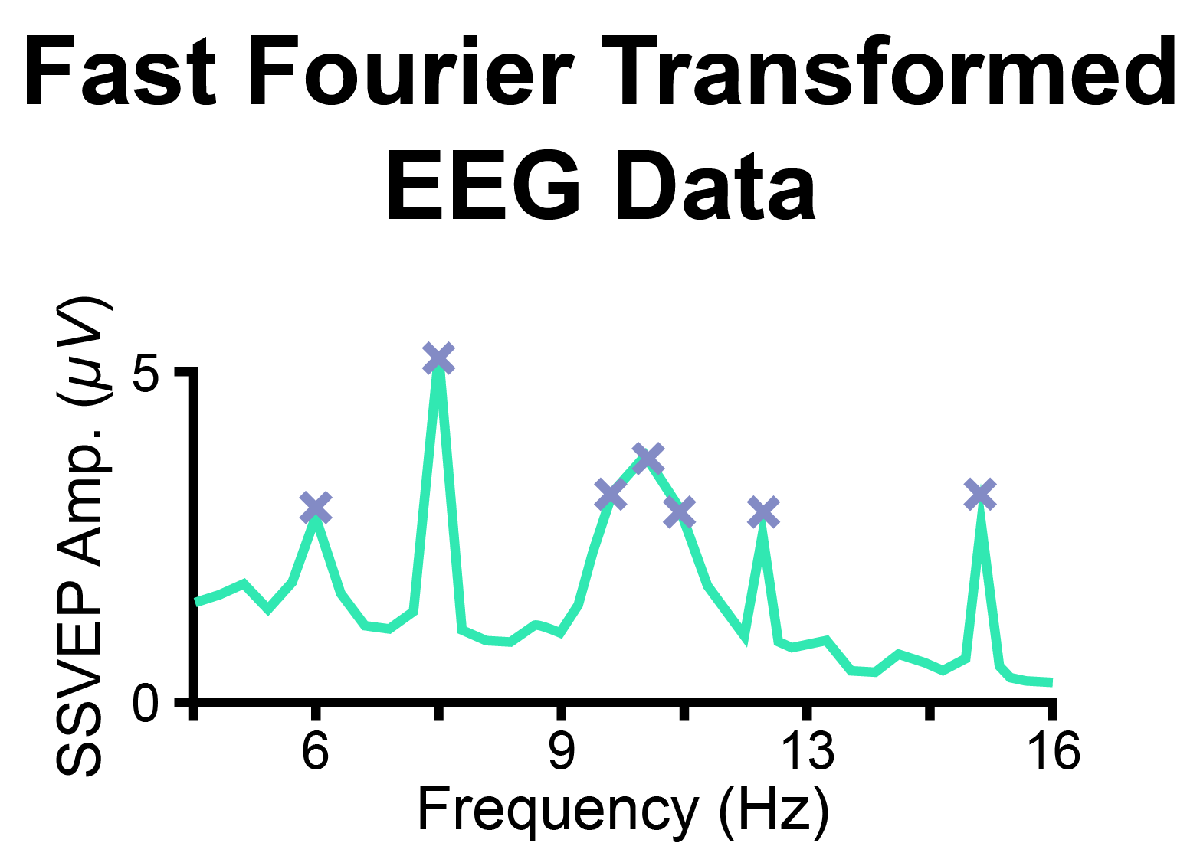

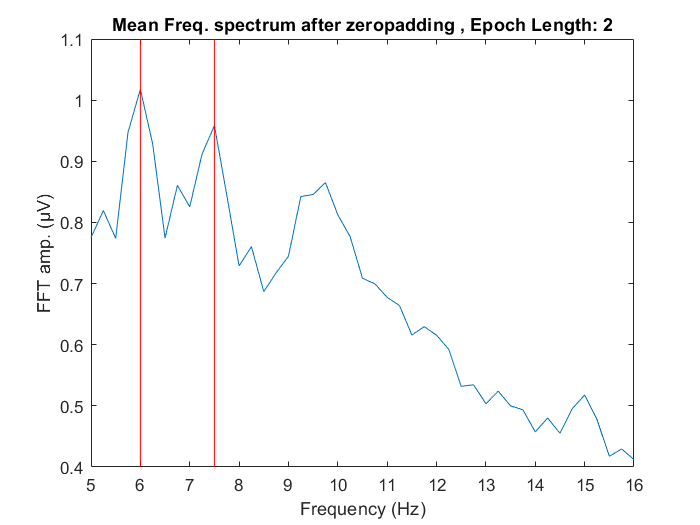

% Zero padding - pad chunk of data out to achieve adequete spectral resolution.
padlength = (n.x-chunksize)/2;
padding = zeros(padlength, n.channels, n.epochs);

DATA2 = cat(1, padding, DATA, padding);

% run FFT
tmp = abs( fft( DATA2(:,:,~~LABELS(:,4)) ) )/n.x;
tmp(2:end-1,:,:) = tmp(2:end-1,:,:)*2;

% Plot frequency spectrum
figure;
plot(f, nanmean(nanmean(tmp,2),3))
xlim([5 16])
line([Hz(1) Hz(1); Hz(2) Hz(2)]', [get(gca, 'ylim');get(gca, 'ylim')]', 'color', 'r')
ylabel('FFT amp. (µV)'); xlabel('Frequency (Hz)')
title(['Mean Freq. spectrum after zeropadding , Epoch Length: ' num2str(time.chunksizes(chunkSizeIterator)) ])

### Run FFT and get SSVEPs at the correct frequencies

% run FFT
tmp = abs( fft( DATA2) )/n.x;
tmp(2:end-1,:,:) = tmp(2:end-1,:,:)*2;

% Take SSVEPs at the correct frequency
switch HZSTATE
    case 1
        AMP_RAW = tmp(idx.Hz(1:2)  ,:,:);
    case 2
        AMP_RAW = tmp(idx.Hz  ,:,:);
    case 3
        alpha = mean( tmp(idx.Hz_alpha  ,:,:),1);
        AMP_RAW = cat(1, tmp(idx.Hz(1:2)  ,:,:), alpha);
    case 4
        alpha = mean( tmp(idx.Hz_alpha  ,:,:),1);
        AMP_RAW = cat(1, tmp(idx.Hz  ,:,:), alpha);
end

## Lets train and test some classifiers!

### 1. Z-Scoring

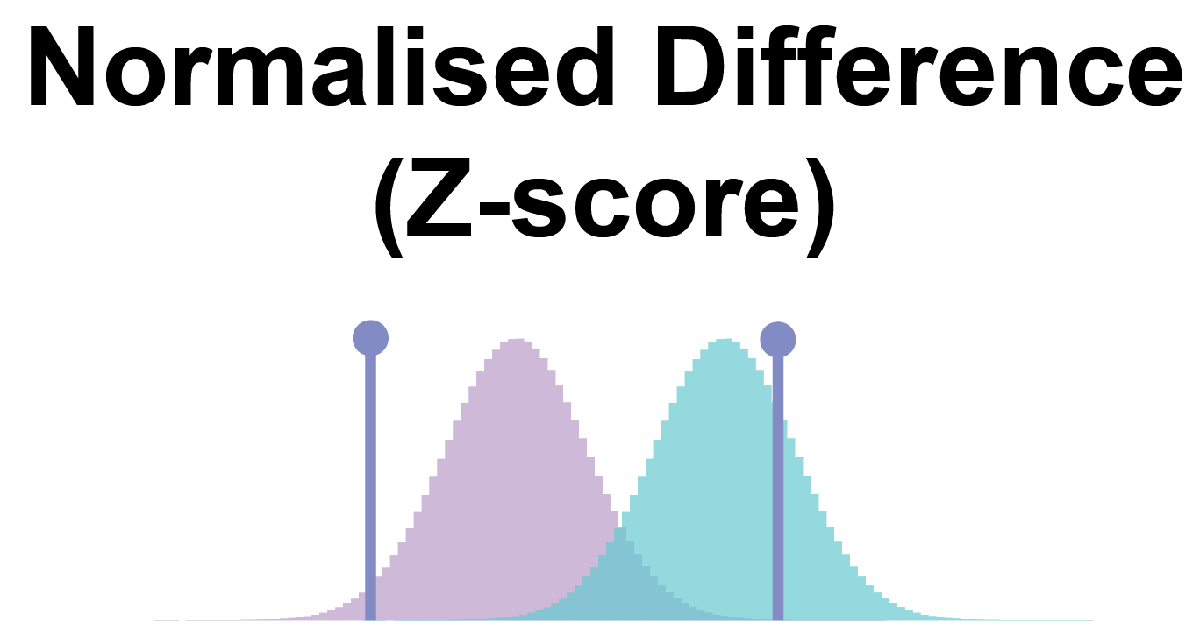

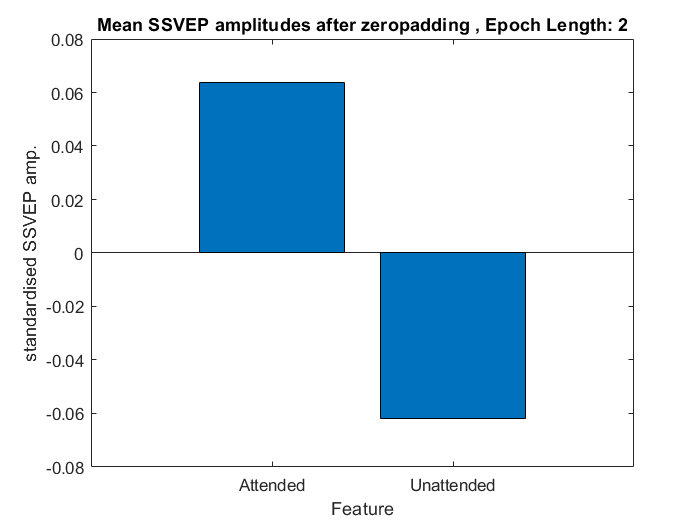

if HZSTATE==1
    % Z-score SSVEPs
    
    AMPALL = NaN(2,n.epochs);
    
    tmp = squeeze(nanmean(AMP_RAW,2));
    
    % Take mean and std on chunks that weren't corrupted by noise
    MEAN = mean(tmp(:,~~LABELS(:,4)),2);
    STD = std(tmp(:,~~LABELS(:,4))')';
    
    % Z-score
    AMPALL(1,:) = (tmp(1,:)-MEAN(1))./STD(1);
    AMPALL(2,:) = (tmp(2,:)-MEAN(2))./STD(2);
    
    %         AMPALL(1,:) = zscore(tmp(1,:));
    %         AMPALL(2,:) = zscore(tmp(2,:));
    
    % switch ordering from [6Hz, 7.5Hz] to [attended, unattended].
    indices = [1 2; 2 1];
    for ii = 1:n.epochs
        AMPALL(:,ii) = AMPALL(indices( LABELS(ii,1),:), ii) ;
    end
    
    % Plot bar graph of SSVEPs
    M = mean(mean(AMPALL,2),3);
    figure;
    bar(M)
    xlim([0 3])
    set(gca, 'xTickLabel', {'Attended' 'Unattended'})
    xlabel('Feature')
    ylabel('standardised SSVEP amp.')
    title(['Mean SSVEP amplitudes after zeropadding , Epoch Length: ' num2str(time.chunksizes(chunkSizeIterator)) ])
    
    % Get Features
    FEATURE = AMPALL;%squeeze(mean(AMPALL,2)); % average across channels
    FEATURE = FEATURE(1,:) - FEATURE(2,:);
    
    % Get accuracy
    ACCURACY_ALL.zscore{chunkSizeIterator} = sign(FEATURE)==1;
    
end

### 2-3. Linear Discriminant Analysis, K-Nearest Neighbour

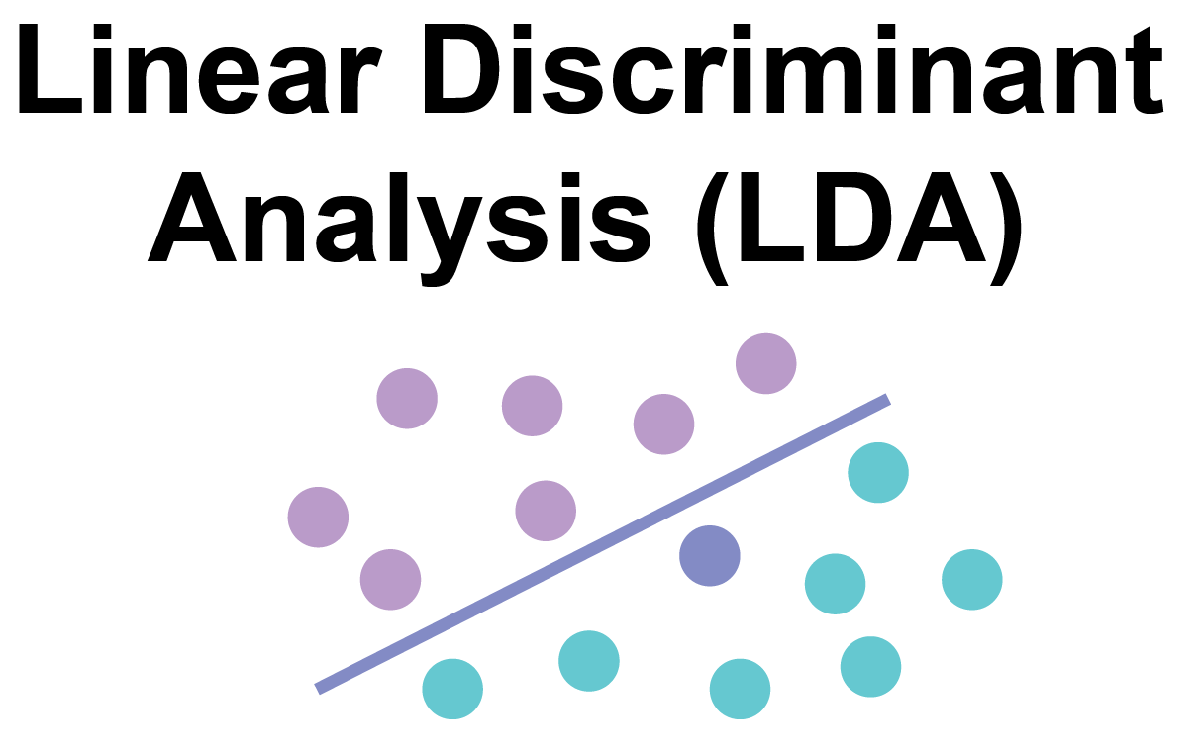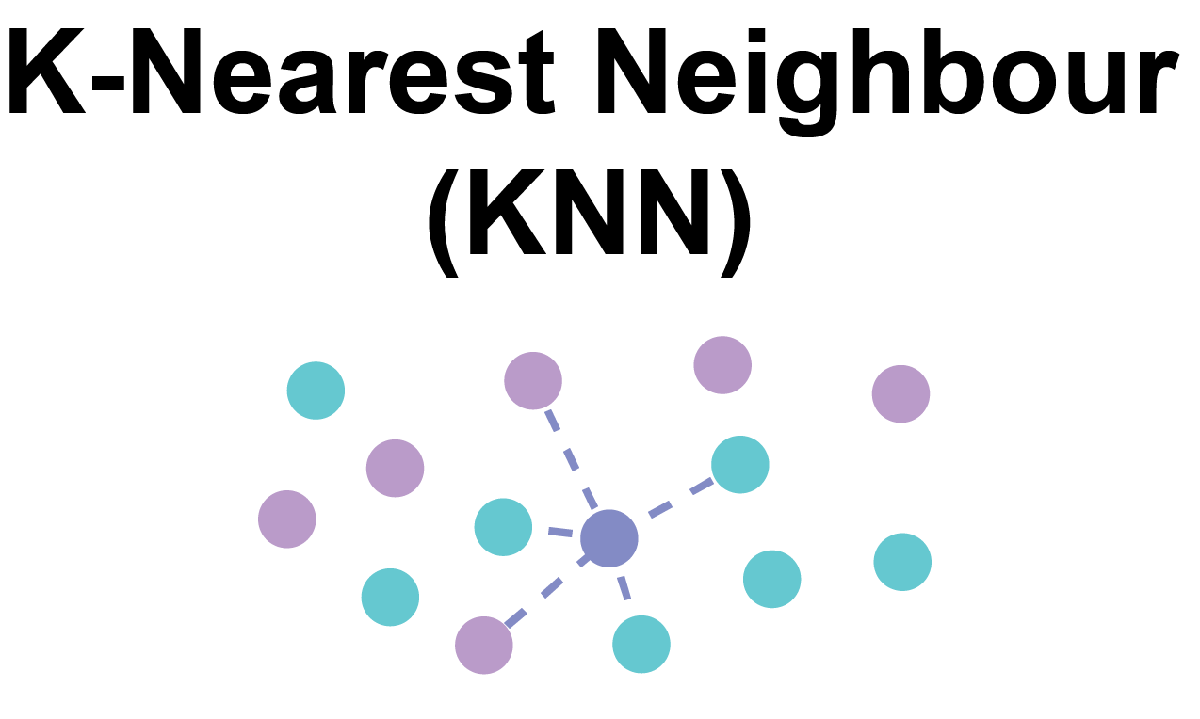


% get feature vector
tmp = AMP_RAW(1,:,:);
for HH = 2:size(AMP_RAW,1)
    tmp = cat(2, tmp, AMP_RAW(HH,:,:));
end
FEATURE = squeeze(tmp);

% Preallocate
ACCURACY_ALL.LDA.(str.HzState{HZSTATE}){chunkSizeIterator} = NaN(n.epochs,1);
%     ACCURACY_ALL.SVM.(str.HzState{HZSTATE}){chunkSizeIterator} = NaN(n.epochs,1);
ACCURACY_ALL.KNN.(str.HzState{HZSTATE}){chunkSizeIterator} = NaN(n.epochs,1);

% Fold through
for FOLD = 1:n.trials
    
    % Organise data
    idx_test = LABELS(:,2)==FOLD;
    %         idx_train = LABELS(:,2)~=FOLD;
    idx_train = LABELS(:,2)~=FOLD & LABELS(:,4); % exclude trials with exessive noise from training
    
    inputs_train = FEATURE(:,idx_train)';
    labels_train = LABELS(idx_train,1);
    
    inputs_test = FEATURE(:,idx_test)';
    labels_test = LABELS(idx_test,1);
    
    % Train Classifiers
    classifier_LDA = fitcdiscr( inputs_train, labels_train);
    classifier_KNN = fitcknn( inputs_train, labels_train);
    %         classifier_SVM = fitcsvm( inputs_train, labels_train);
    
    % Test
    y_predict = predict( classifier_LDA, inputs_test );
    ACCURACY_ALL.LDA.(str.HzState{HZSTATE}){chunkSizeIterator}(idx_test) = y_predict == labels_test;
    
    y_predict = predict( classifier_KNN, inputs_test );
    ACCURACY_ALL.KNN.(str.HzState{HZSTATE}){chunkSizeIterator}(idx_test) = y_predict == labels_test;
    
    %         y_predict = predict( classifier_SVM, inputs_test );
    %         ACCURACY_ALL.SVM{chunkSizeIterator}(idx_test) = y_predict == labels_test;
    
end


### 4. Multi-layer Perceptron

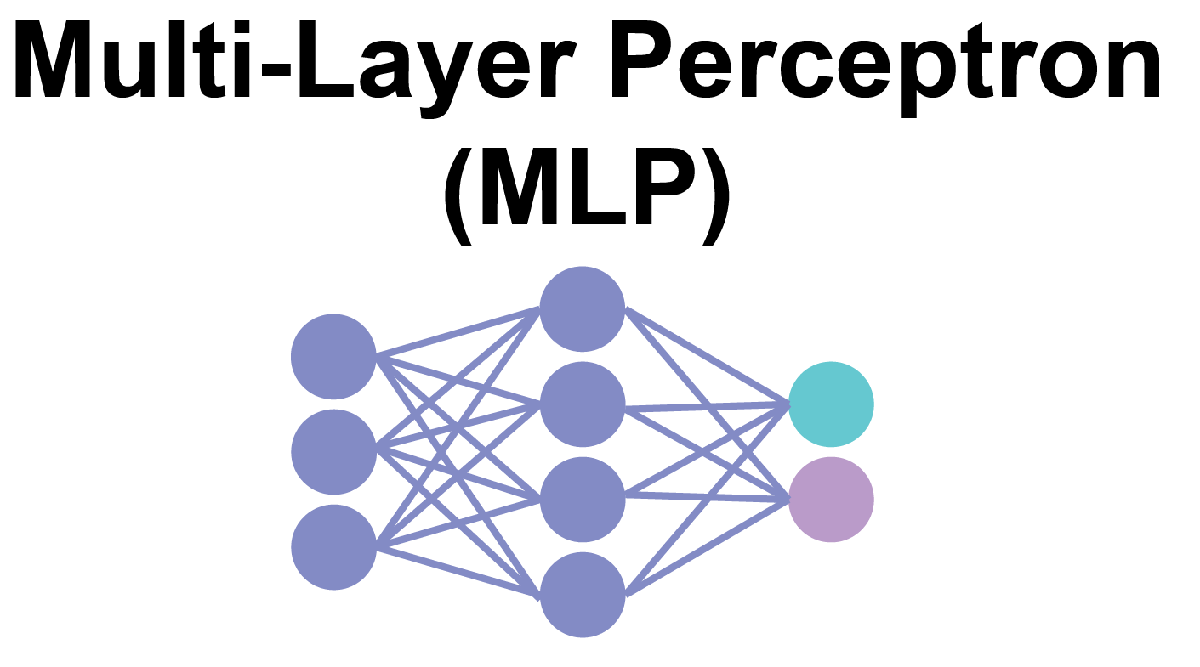

% Preallocate
ACCURACY_ALL.MLP.(str.HzState{HZSTATE}){chunkSizeIterator} = NaN(n.epochs,1);

% Fold through
for FOLD = 1:n.trials
    %         disp(FOLD)
    % Organise data
    idx_test = LABELS(:,2)==FOLD;
    %         idx_train = LABELS(:,2)~=FOLD;
    idx_train = LABELS(:,2)~=FOLD & LABELS(:,4); % exclude trials with exessive noise from training
    
    inputs_train = FEATURE(:,idx_train)';
    labels_train = LABELS(idx_train,1);
    
    inputs_test = FEATURE(:,idx_test)';
    labels_test = LABELS(idx_test,1);
    
    % Labels need to be stored slightly differently for MLP
    tt = zeros(2, length(labels_train));
    tt(1,labels_train==1) = 1; tt(2,labels_train==2) = 1;
    
    % create empty net
    net = patternnet(hiddenLayerSize, trainFcn, performFcn);
    
    
    %## Train the Network
    [net,tr] = train(net,inputs_train',tt);
    
    % Test
    y_predict = net(inputs_test');
    ACCURACY_ALL.MLP.(str.HzState{HZSTATE}){chunkSizeIterator}(idx_test) = vec2ind(y_predict)'  == labels_test;
    
end
sum(ACCURACY_ALL.MLP.(str.HzState{HZSTATE}){chunkSizeIterator})/length(ACCURACY_ALL.MLP.(str.HzState{HZSTATE}){chunkSizeIterator})

ans = 0.5139

### 5. Filter-Bank Canonical Correlation Analysis

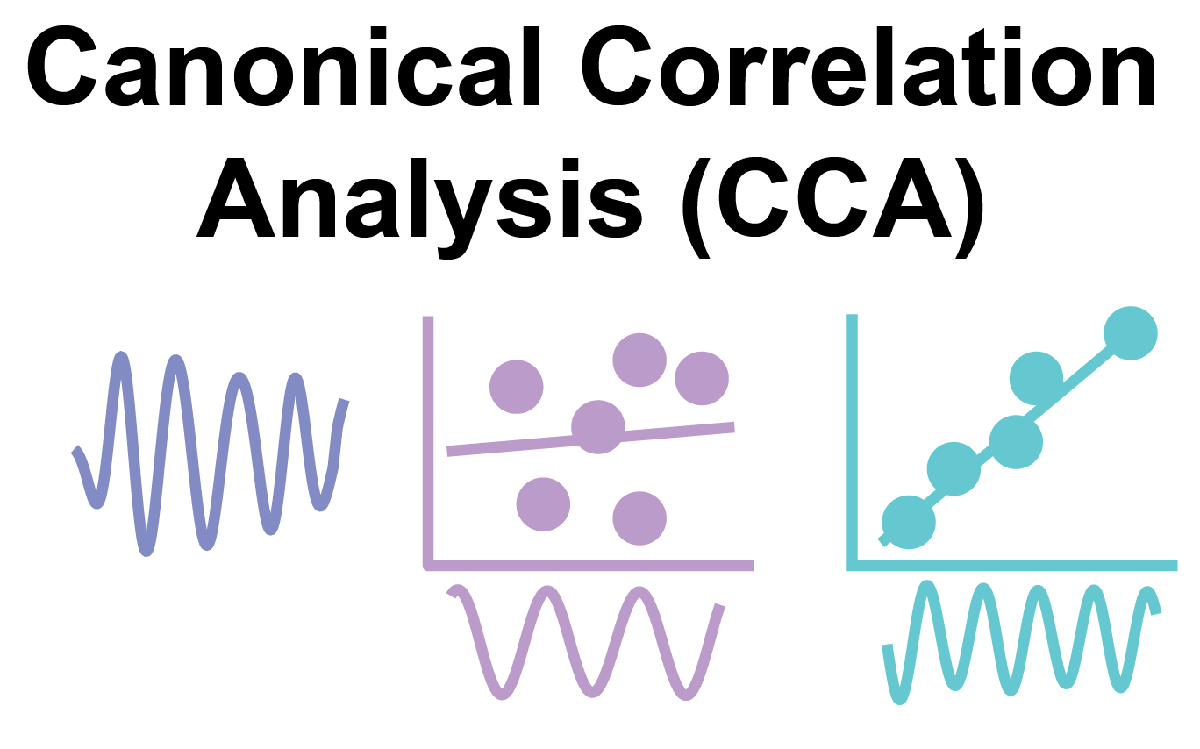

% preallocate
ACCURACY_arranged.CCA{chunkSizeIterator} = NaN(n.chunks, n.trials);

for FOLD = 1:n.trials % leave one out
    RHO = NaN(n.chunks, n.Hz_main);
    for CHUNK = 1:n.chunks % for each chunk of data
        % Select a piece of trial
        start = samplepoints(CHUNK)-chunksize +1;
        stop = samplepoints(CHUNK);
        epoch = start:stop;
        
        for FF2 = 1:n.Hz_main
            
            rho_use = zeros(1,5);
            
            for HH = 1:n.harmonics
                % Get the data and templates we'll use
                erp_cca = CCA_ERP(epoch,HH,FF2,FOLD);
                synth_cca = CCA_SIN(epoch,HH,FF2,FOLD);
                
                trial2classify_long = trial_harm( epoch, :,FOLD, HH );
                trial2classify = mean( trial2classify_long, 2);
                
                if ~all( trial2classify(:) == 0 )
                    
                    % ------- canncor
                    
                    % -- test(X) V synth(Y)
                    [WXyX,WXyY,~,~,~] = canoncorr(trial2classify, synth_cca);
                    [~,~,r,~,~] = canoncorr(trial2classify_long, synth_cca);
                    rho_tmp(1) = max(r);
                    
                    % -- test(X) V train(x)
                    [WXxX,WXxx,~,~,~] = canoncorr(trial2classify, erp_cca);
                    [~,~,r,~,~] = canoncorr(trial2classify_long, erp_cca);
                    rho_tmp(2) = max(r);
                    
                    % -- train(x) V synth(Y)
                    [WxYx,WxYY,~,~,~] = canoncorr(trial2classify, erp_cca);
                    
                    % -- test(X) V train(x) -- Weight(test(X) V synth(Y))
                    X = trial2classify; Y = erp_cca;
                    U = (X - repmat(mean(X),size(X,1),1))*WXyX;
                    V = (Y - repmat(mean(Y),size(X,1),1))*WXyY;
                    r = corr(U,V);
                    rho_tmp(3) = max(diag(r));
                    
                    % -- test(X) V train(x) -- Weight(train(x) V synth(Y))
                    X = trial2classify; Y = erp_cca;
                    U = (X - repmat(mean(X),size(X,1),1))*WxYx;
                    V = (Y - repmat(mean(Y),size(X,1),1))*WxYY;
                    r = corr(U,V);
                    rho_tmp(4) = max(diag(r));
                    
                    % -- train(X) V train(x) -- Weight(train(x) V test(x))
                    X = erp_cca; Y = erp_cca;
                    U = (X - repmat(mean(X),size(X,1),1))*WXxX;
                    V = (Y - repmat(mean(Y),size(X,1),1))*WXxx;
                    r = corr(U,V);
                    rho_tmp(5) = max(r);
                    
                else
                    rho_tmp(1:5) = 0;
                end
                
                %% create weighted combinations
                
                div = HH;
                rho_use(1) = rho_use(1) + (1/div)*(rho_tmp(1)^2);
                rho_use(2) = rho_use(2) + (1/div)*(rho_tmp(2)^2);
                rho_use(3) = rho_use(3) + (1/div)*(rho_tmp(3)^2);
                rho_use(4) = rho_use(4) + (1/div)*(rho_tmp(4)^2);
                rho_use(5) = rho_use(5) + (1/div)*(rho_tmp(5)^2);
                
                
            end
            
            % -- combine different R values
            RHO(CHUNK, FF2) = ...
                (sign(rho_use(1))*rho_use(1)^2)+...
                (sign(rho_use(2))*rho_use(2)^2)+...
                (sign(rho_use(3))*rho_use(3)^2)+...
                (sign(rho_use(4))*rho_use(4)^2)+...
                (sign(rho_use(5))*rho_use(5)^2);
            
        end
    end
    
    [~,idx.tmp]= max(RHO, [],2);
    ACCURACY_arranged.CCA{chunkSizeIterator}(:,FOLD) = idx.tmp == LABELS_EEG(FOLD);
end

ACCURACY_ALL.CCA{chunkSizeIterator} = ACCURACY_arranged.CCA{chunkSizeIterator}(:);


### Rearrance all the accuracy outputs by trial and chunk

Here, we rearrange the data into a structure which is easier to plot.


for MM = 1:n.methods-1
    if any(strcmp(methods{MM}, {'LDA'    'KNN'    'MLP'}))
        
            ACCURACY_arranged.(methods{MM}).(str.HzState{HZSTATE}){chunkSizeIterator} = NaN(n.chunks, n.trials);
    else
        ACCURACY_arranged.(methods{MM}){chunkSizeIterator} = NaN(n.chunks, n.trials);
    end
end

for TRIAL = 1:n.trials
    for CHUNK = 1:n.chunks
        idx.tmp = LABELS(:,2) == TRIAL & LABELS(:,3) == CHUNK;
        for MM = 1:n.methods-1
            if any(strcmp(methods{MM}, {'LDA'    'KNN'    'MLP'}))
                
                    ACCURACY_arranged.(methods{MM}).(str.HzState{HZSTATE}){chunkSizeIterator}(CHUNK, TRIAL) = ACCURACY_ALL.(methods{MM}).(str.HzState{HZSTATE}){chunkSizeIterator}(idx.tmp);
            else
                ACCURACY_arranged.(methods{MM}){chunkSizeIterator}(CHUNK, TRIAL) = ACCURACY_ALL.(methods{MM}){chunkSizeIterator}(idx.tmp);
            end
        end
    end
end


### Plot the results by decoding method

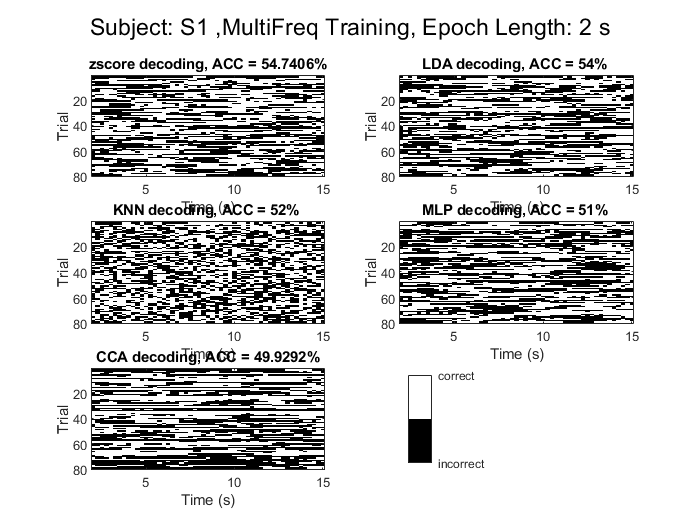


h = figure;
for MM = 1:n.methods
    %% Plot result
    subplot(ceil(n.methods/2), 2,MM)
    if any(strcmp(methods{MM}, {'LDA'    'KNN'    'MLP'}))
        
        imagesc(samplepoints./fs, 1:n.trials,   ACCURACY_arranged.(methods{MM}).(str.HzState{1}){chunkSizeIterator}')
        
        title([methods{MM} ' decoding, ACC = ' ...
            num2str(round(mean(ACCURACY_ALL.(methods{MM}).(str.HzState{HZSTATE}){chunkSizeIterator})*100)) '% ' ...
            ])
    else
        imagesc(samplepoints./fs, 1:n.trials,   ACCURACY_arranged.(methods{MM}){chunkSizeIterator}')
        title([methods{MM} ' decoding, ACC = ' num2str(mean(ACCURACY_ALL.(methods{MM}){chunkSizeIterator})*100) '%'])
    end
    ylabel('Trial')
    xlabel('Time (s)')
    colormap([0 0 0; 1 1 1])
end

% add colorbar
subplot(ceil(n.methods/2), 2,MM+1)
axis('off')
c=colorbar;
c.Ticks = [0,1];
c.TickLabels = {'incorrect' 'correct'};
c.Location = 'west';

% Add title
tit = [ 'Subject: ' str.sub ' ,' str.attnstate{ATTNSTATE} ' Training, Epoch Length: ' num2str(time.chunksizes(chunkSizeIterator)) ' s'];
suptitle(tit)

## Summary

This is the basic code that was used to run the analysis.

We cycled through these classification approaches for each subject (1-30), sliding window length (0.25 s, 0.5 s, 1 s, 2 s, 4 s), combination of frequencies (fundamental flicker frequencies, +harmonics, +alpha, +alpha and harmonics) and training dataset (individual presentation, concurrent presentaion. The resulting average classification accuracies were as follows: